ORGANIC RANKINE CYCLE

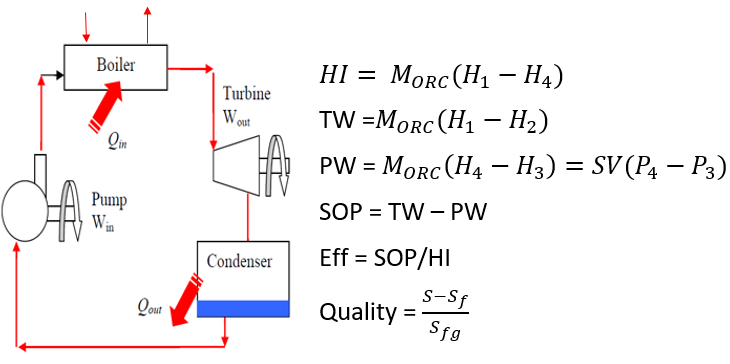

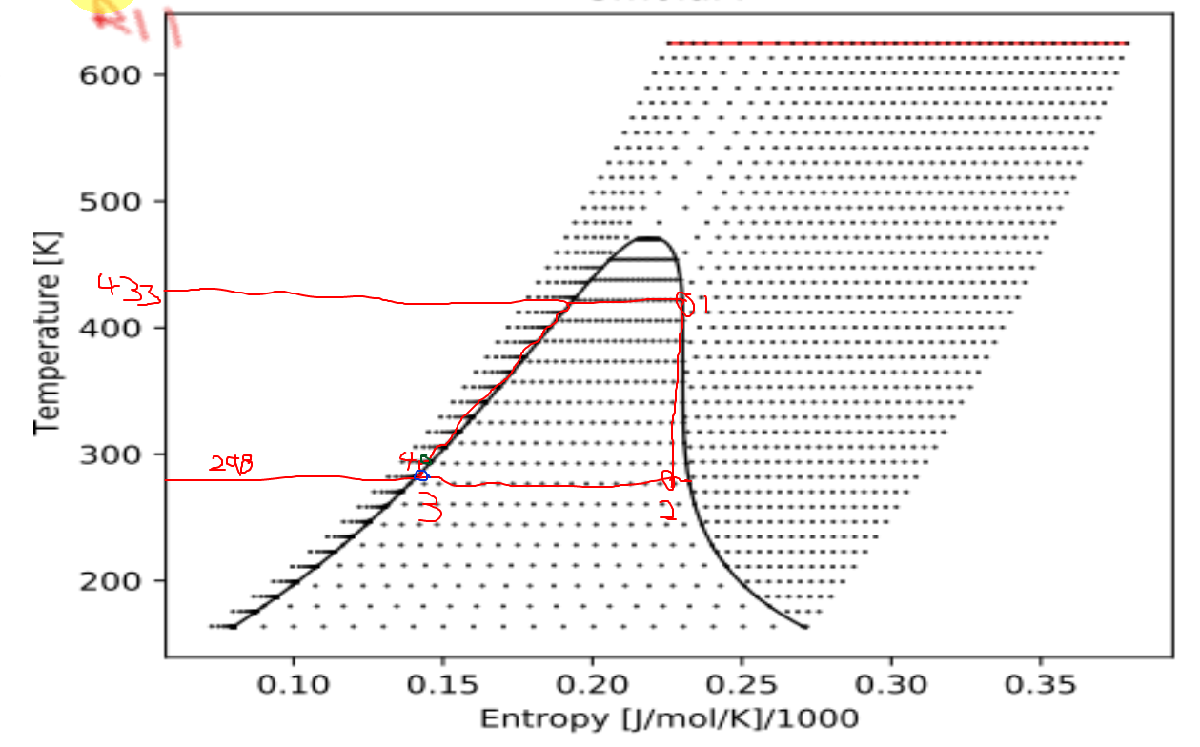              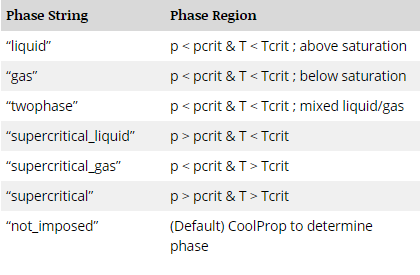

                              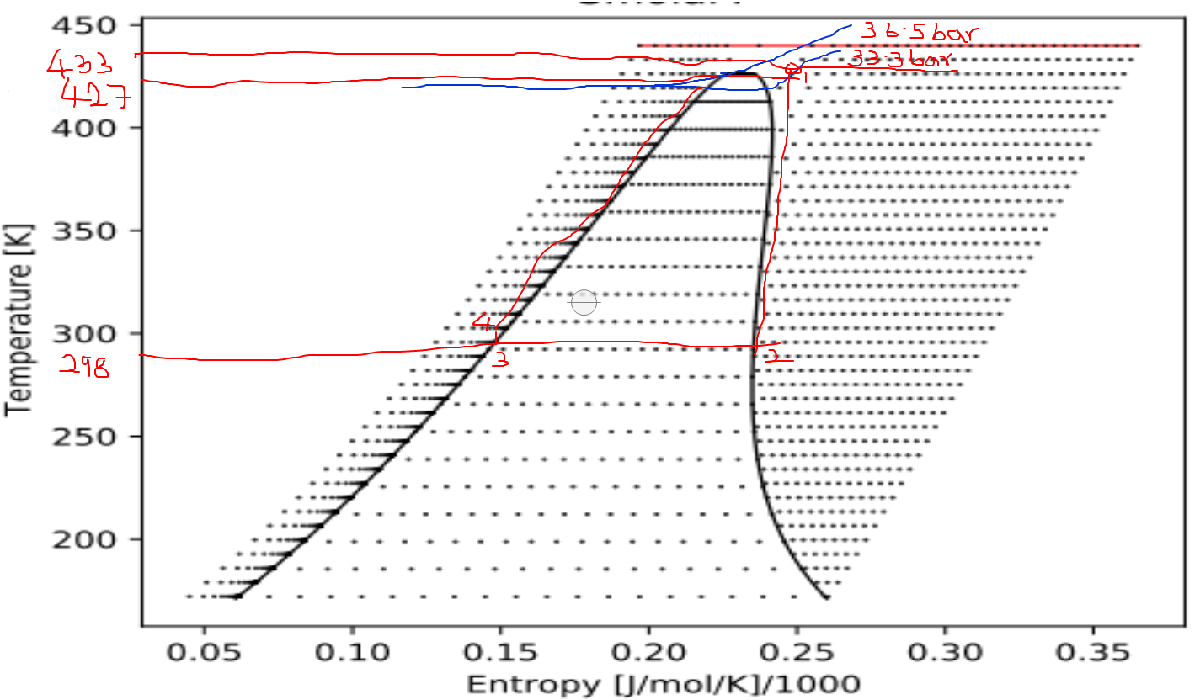

Input Parameters

%Turbine Inlet Conditions

T_1 = 433 % Boiler exit temperature kelvin

T_1 = 433

P_1 = 3330000 % Pa

P_1 = 3330000

M_ORC = 1  % kg/s

M_ORC = 1

Turb_eff = 0.92  %Turbine efficiency

Turb_eff = 0.9200

Thermodynamic properties at point 1

H_1 = py.CoolProp.CoolProp.PropsSI('H', 'T', T_1, 'P|supercritical_gas', P_1, 'R245fa') %J/kg 

H_1 = 5.1376e+05

H_1test = py.CoolProp.CoolProp.PropsSI('H', 'T', T_1, 'P|not_imposed', P_1, 'R245fa') %J/kg 

H_1test = 5.1376e+05

S_1 = py.CoolProp.CoolProp.PropsSI('S', 'T', T_1, 'P|supercritical_gas', P_1, 'R245fa')  % J/kg/K

S_1 = 1.8501e+03

%D_1 = py.CoolProp.CoolProp.PropsSI('D', 'T', T_1, 'Q', 1, 'R11')  % kg/m^3

Thermodynamic Properties at Point 2

T_2 = 298 % kelvin

T_2 = 298

S_2 = S_1 % J/kg/K

S_2 = 1.8501e+03

H_2 = py.CoolProp.CoolProp.PropsSI('H', 'T', T_2, 'Q', 1, 'R245fa') % J/kg

H_2 = 4.2410e+05

Thermodynamic Properties at Point 3

Pump_eff = 0.89

Pump_eff = 0.8900

T_3 = 298 % kelvin

T_3 = 298

P_3 = py.CoolProp.CoolProp.PropsSI('P', 'T', T_2, 'Q', 0, 'R245fa') % Pa

P_3 = 1.4776e+05

D_3 = py.CoolProp.CoolProp.PropsSI('D', 'T', T_2, 'Q', 0, 'R245fa') % kg/m^3

D_3 = 1.3389e+03

SV_3 = 1/D_3 % m^3/kg

SV_3 = 7.4690e-04

H_3 = py.CoolProp.CoolProp.PropsSI('H', 'T', T_2, 'Q', 0, 'R245fa') % J/kg

H_3 = 2.3278e+05

Thermodynamic Properties at Point 4

P_4 = P_1 % Pa

P_4 = 3330000

PW = (SV_3 * (P_4 - P_3))/Pump_eff % J/kg

PW = 2.6706e+03

H_4 = H_3 + PW  % J/kg

H_4 = 2.3546e+05

Performance

HI = M_ORC * (H_1 - H_4) % J/kg

HI = 2.7830e+05

TW = (M_ORC * (H_1 - H_2))*Turb_eff % J/kg

TW = 8.2491e+04

SOP = TW - PW % J/kg

SOP = 7.9821e+04

Cycle_eff = SOP/HI

Cycle_eff = 0.2868